# Numerical Calculus (2/4)

-----

# 2. Derivatives


A     = 1.1; % fluorescence intensity units
omega = 2.6; % rad/s
A_0   = 0.01;

u=@(t) A*sin(omega*t)+A_0;

tArray = linspace(0,1.6,200);
uArray = u(tArray); % an array of samples of u



## 2.1 Rates of change, the numerical derivative and the derivative via rules of differentiation

For a given change in time dt, how much does u change? Does it increase or decrease?

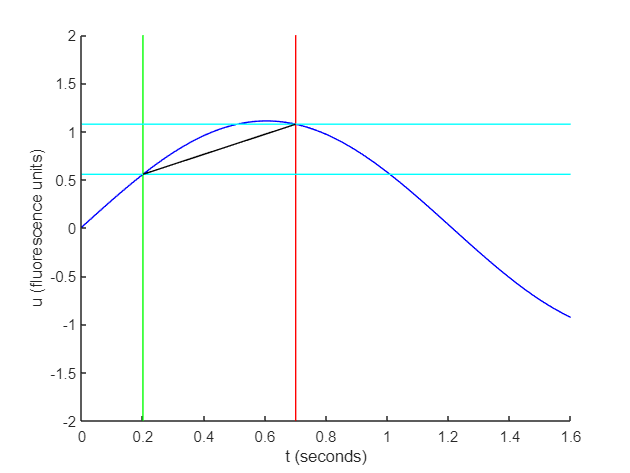

figure; hold on;
plot(tArray,uArray, '-b');
ylabel('u (fluorescence units)');
xlabel('t (seconds)');
tMax = 1.6;

% time at which to compute the change
t = 0.2; % seconds
plot([t, t], [-2, 2], '-g'); % vertical line

% change in t
dt = 0.5; % seconds
plot([t+dt, t+dt], [-2, 2], '-r'); % vertical line

% change in u
du = u(t+dt) - u(t);
plot([0,tMax], [u(t), u(t)], '-c'); % horizontal lines
plot([0,tMax], [u(t+dt), u(t+dt)], '-c'); % horizontal lines

% slope
plot([t,t+dt], [u(t), u(t+dt)], '-k'); % slope lines

display(du/dt); % fluorescence units per second

    1.0389



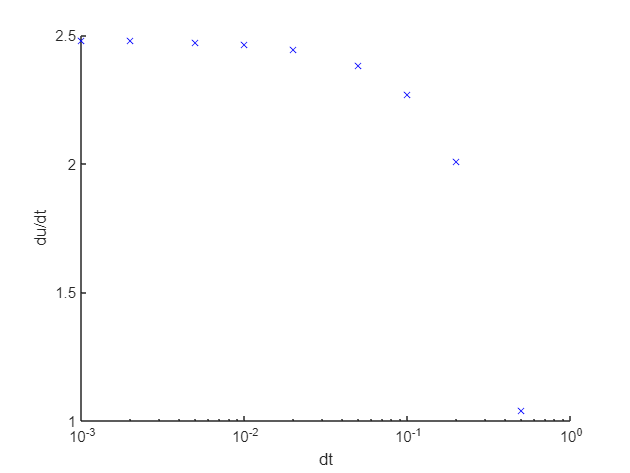

% time at which to compute the change
t = 0.2; % seconds

figure; hold on;
for dt=[0.5 0.2 0.1 0.05 0.02 0.01 0.005 0.002 0.001]
    
    % rate of change
    dudt = (u(t+dt) - u(t))/dt; % 'dudt' is a convenient shorthand for 'du/dt' (which can't be a variable name)
    
    plot(dt,dudt, 'bx')
end % finished loop through dt's


ylabel('du/dt'); xlabel('dt');
set(gca,'xscale','log');

The rate of change over an infinitesimally small period of time is the *derivative*.

The numerical derivative (this is called *finite difference* estimate of the derivative) is:

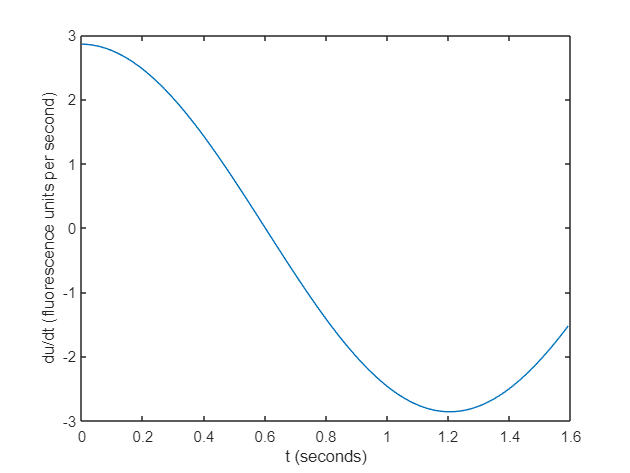

dudt = diff(u(tArray))./diff(tArray);
figure
plot(tArray(1:end-1), dudt); % How many samples of the derivative do you have? *******************
ylabel('du/dt (fluorescence units per second)'); xlabel('t (seconds)');

If you have an analytical formula for u(t), there are shortcuts for analytically computing the derivative. These are called the rules of differentiation.


$$f(t) = t^2$$



$$df/dt = ?$$



$$g(t) = A_g*\sin(t^2) \cdot \exp((-4/\tau) \cdot t)$$



$$dg/dt = .....$$


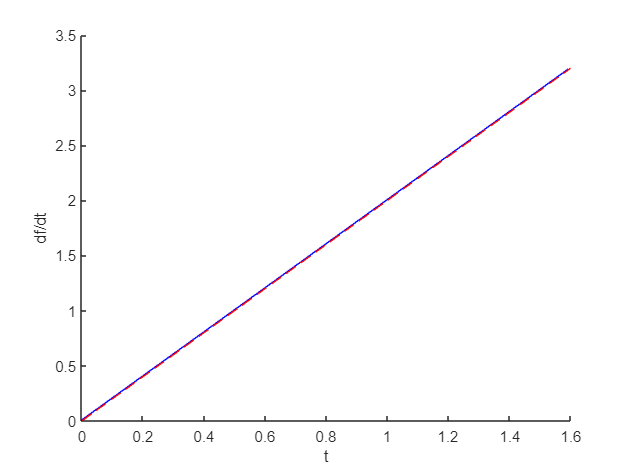

figure; hold on;
fArray = tArray.^2;
dfdt = diff(fArray)./diff(tArray);
plot(tArray(1:end-1),dfdt, '-b'); % the numerical derivative via finite differences

plot(tArray, 2*tArray, '--r'); % the derivative via an analytical method (the rules of differentiation)
ylabel('df/dt'); xlabel('t');

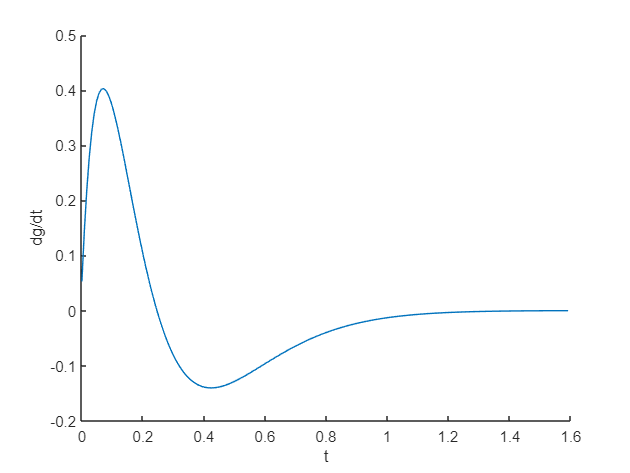

Ag = 7; 
tau = 0.5;

gArray = Ag*sin(tArray.^2).*exp(-4/tau*tArray);

dgdt = diff(gArray)./diff(tArray); % numerical derivative via finite differences

figure; hold on;
plot(tArray(1:end-1),dgdt);
ylabel('dg/dt'); xlabel('t');

## 2.2 Higher derivatives and Taylor series

The derivative of the derivative is called the second derivative. And so on.

If you can estimate the first nPoly derivatives of any function f(x), then you can build a *polynomial* that matches all those nPoly derivatives. 

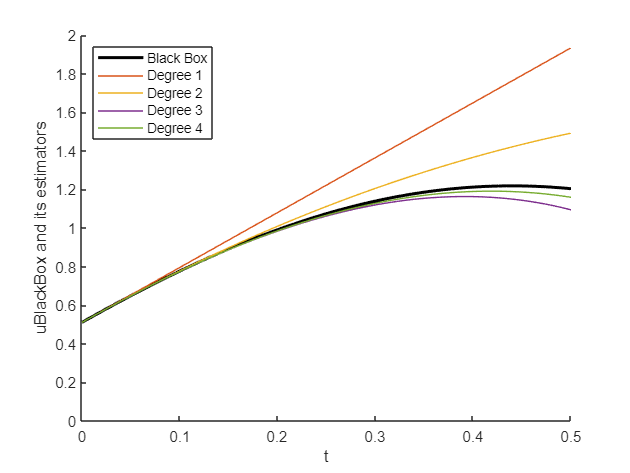

uArray = uBlackBox(tArray);

% finite-difference estimates of the first 4 derivatives
dt = tArray(2)-tArray(1); 

dudt   = diff(uArray)/dt;
d2udt2 = diff(dudt)/dt;
d3udt3 = diff(d2udt2)/dt;
d4udt4 = diff(d3udt3)/dt; % How many samples do you have for the nth derivative? ************

% Taylor polynomials
Taylor1 =@(t) uArray(1) + dudt(1)*t;
Taylor2 =@(t) uArray(1) + dudt(1)*t + 1/2*d2udt2(1)*t.^2;
Taylor3 =@(t) uArray(1) + dudt(1)*t + 1/2*d2udt2(1)*t.^2 + 1/6*d3udt3(1).*t.^3;
Taylor4 =@(t) uArray(1) + dudt(1)*t + 1/2*d2udt2(1)*t.^2 + 1/6*d3udt3(1).*t.^3 + 1/24*d4udt4(1).*t.^4;

figure;
hold on;
plot(tArray,uArray, '-k', 'linewidth',2);

plot(tArray,Taylor1(tArray));
plot(tArray,Taylor2(tArray));
plot(tArray,Taylor3(tArray));
plot(tArray,Taylor4(tArray));

set(gca,'ylim', [0,2], 'xlim', [0,0.5]);
ylabel('uBlackBox and its estimators');
xlabel('t');
legend('Black Box','Degree 1', 'Degree 2','Degree 3','Degree 4','Location','northwest');

## 2.3 Mini exercise: Sampling with a bit of noise

The following code generates a sample of u, with a little bit of noise. The noise is a random variable (Gaussian) with standard deviation sigma =0.0001. 

- Make a plot of the first derivative estimate from finite differences.

- Make a plot of the 2nd and 3rd derivatives estimated from finite differences.

- What is the amount of noise (measured by standard deviation) to get all 3 derivatives accurate to within 10% of the true (analytic) value?

Hint: You have numel(tArray) samples for u. How many samples do you have for dudt? How many for du2dt2?

% ------------------------------------------------------
A     = 1.1; % fluorescence intensity units
omega = 2.6; % rad/s
A_0   = 0.01;

u=@(t) A*sin(omega*t)+A_0;

tArray = linspace(0,1.6,200);
uArray = u(tArray); % an array of samples of u
% ------------------------------------------------------

% analytical solutions (in real life, we might not know these)
dudtExact      =  A*omega*cos(omega*tArray);
du2dt2Exact    = -A*omega^2*sin(omega*tArray);
du3dt3Exact    = -A*omega^3*cos(omega*tArray);

% Take the sample and add a bit of noise
 uObserved = u(tArray) + (1e-1)*randn(size(tArray));
 
display(uObserved);

uObserved =     0.1442   -0.0659    0.2378    0.0415   -0.0433    0.0629    0.2411    0.2760    0.2091    0.2445    0.3016    0.1148    0.2249    0.1223    0.2824    0.4442    0.4428    0.6215    0.4309    0.2199    0.6256    0.6058    0.4400    0.5410    0.6170    0.5975    0.6485    0.5871    0.6138    0.6456    0.5765    0.8163    0.6928    0.7787    0.6422    0.6374    0.7528    0.7532    0.9142    0.8713    0.8803    0.6970    0.7596    0.8911    0.8502    1.0278    1.0462    0.8670    1.0252    1.0893


display(uArray)

uArray =     0.0100    0.0330    0.0560    0.0789    0.1019    0.1248    0.1476    0.1704    0.1931    0.2157    0.2383    0.2607    0.2831    0.3053    0.3274    0.3493    0.3711    0.3927    0.4142    0.4355    0.4566    0.4775    0.4982    0.5187    0.5390    0.5591    0.5789    0.5984    0.6177    0.6368    0.6555    0.6740    0.6922    0.7101    0.7276    0.7449    0.7619    0.7785    0.7948    0.8107    0.8263    0.8415    0.8564    0.8709    0.8850    0.8988    0.9121    0.9251    0.9376    0.9498


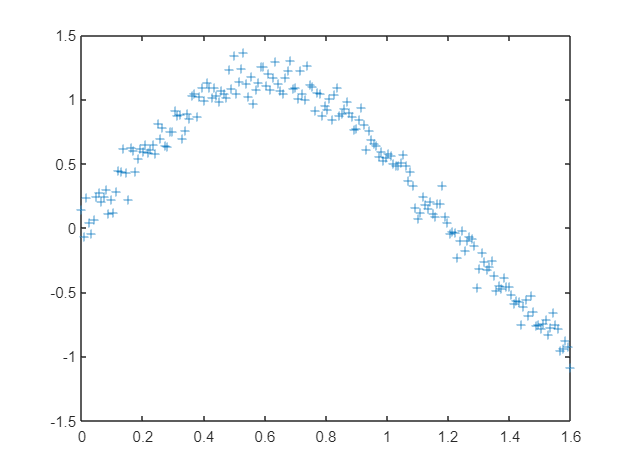

figure;
plot(tArray,uObserved, '+')

## Partial solution below

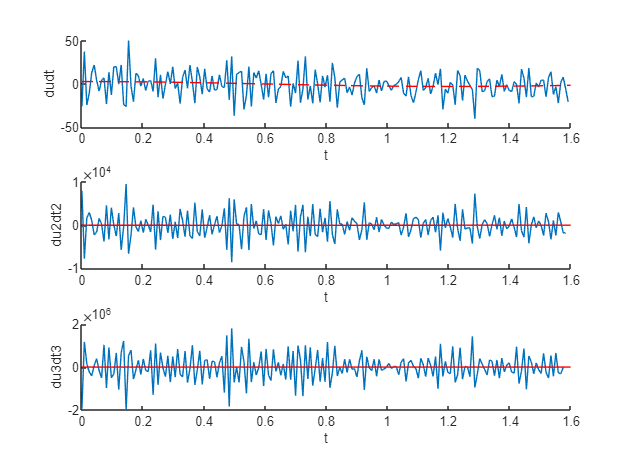

% create finite-difference derivatives for first derivative, second derivative and third derivative
dudt   = diff(uObserved)./diff(tArray);
du2dt2 = diff(dudt)./diff(tArray(1:end-1));
du3dt3 = diff(du2dt2)./diff(tArray(1:end-2));

% and plot them
figure;
subplot(3,1,1); hold on;
plot(tArray(1:end-1), dudt);
plot(tArray, dudtExact, '--r');
xlabel('t');
ylabel('dudt');

subplot(3,1,2); hold on;
plot(tArray(1:end-2), du2dt2);
plot(tArray, du2dt2Exact, '-r');
xlabel('t');
ylabel('du2dt2')

subplot(3,1,3); hold on;
plot(tArray(1:end-3), du3dt3);
plot(tArray, du3dt3Exact, '-r');
xlabel('t');
ylabel('du3dt3')